# **2-ASK ****communication**** system**

% ************************************************************************
% Author: CONG LI
% Date Created: 2023
%
% This script is part of a course project for 
% Communication Systems: Theory and Measurement M
% at University of Bologna.
% ************************************************************************
% ********* Initialization of the environment
clear all % clear all variables
close all % close all plots
clc % clear the screen in the command window

**Signal specifications**

The following code segment initializes signla parameters for a 2-ASK communication system.On the basic of previous activities, the code adds noise to the signals and the demodulator component.

% ********* Signal specifications
bits_per_symbol=1; % number of bits that correspond to a symbol
L=2^bits_per_symbol; % number of levels of the modulation alphabet
nbits=100000*bits_per_symbol; % number of bits to be transmitted
Br=500; % [bits/s] bit rate
fs=50000; % [samples/s] sampling frequency
Ts=1/fs; % sampling time[s].
fc=3000; % [Hz] carrier frequency
Bs=Br/log2(L); % [symbols/s] Symbol rate
nsps=fs/Bs; % samples per symbol

**Pulse shaper specifications**

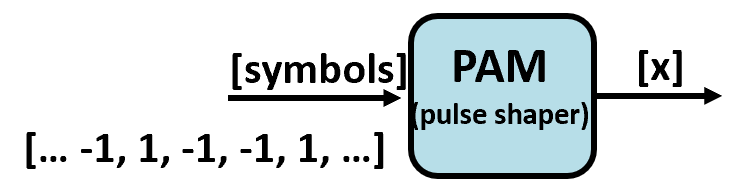

The following code segment initializes the pluse shaper parameters.

% ********* Pulse shaper specifications*
Nf=5*nsps; % number of filter coefficients for the pulse shaper
pulsetype='RECT';
switch pulsetype
case 'ROOTRAISEDCOSINE' % root raised cosine pulse
rolloff=0.8 % roll-off factor for root raised cosine pulses
bandwidth_Hz=0.5*Bs*(1+rolloff); % bandwidth of the baseband signal
case 'RECT' % rectangular pulse,
rolloff=[];
bandwidth_first_lobe_Hz=Bs;
end

**Modulator specifications**

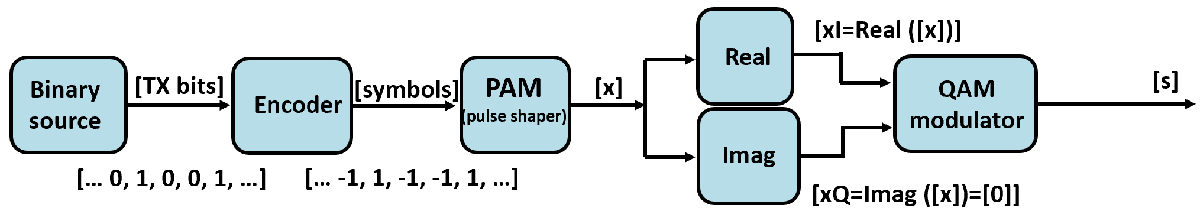

The transmitter has been already implemente in activities.

% ********* Modulator specifications
psi=0; % carrier offset at the receiver
% ********* Monte Carlo simulation
index=1;
for EbN0_dB=1:10 % Run a Monte Carlo simulation for 10 different values of SNR

**Source bits generation**

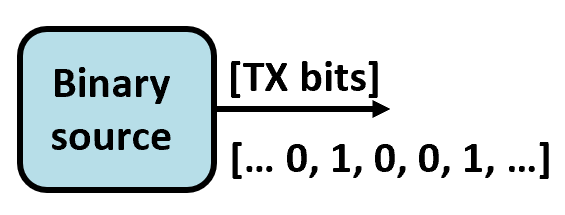

% ********* Source bits generation
source_bits=BinarySource_2023(nbits); % vector with the source bits

**Symbols generation with Gray mapping**

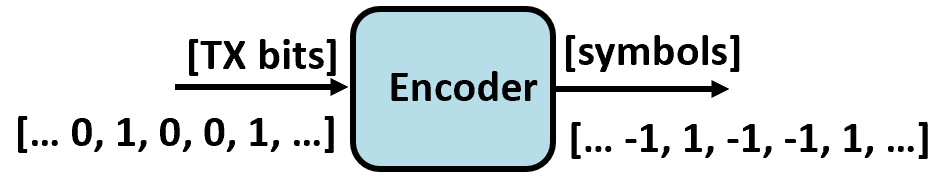

% ********* Symbols generation with Gray mapping
symbols=Encoder_2023(source_bits, L);

**2-ASK modulation through the QAM modulator**

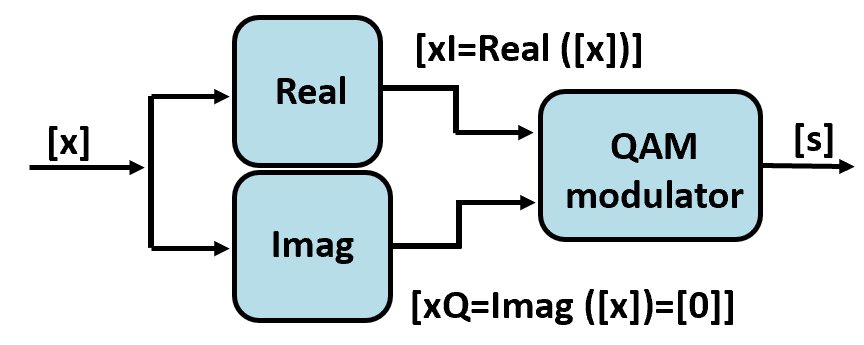

% ********* Generation of the baseband PAM signal
[x,h,DelayPAM]=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff);
T=Ts*(length(x)-1); % signal duration
% ********* 2-ASK modulation through the QAM modulator
xI=x; % in-phase signal
xQ=zeros(1,length(x)); % the quadrature component is zero
s=ModQAM_2023(xI,xQ,fc,T,fs);

**AWGN Channel**

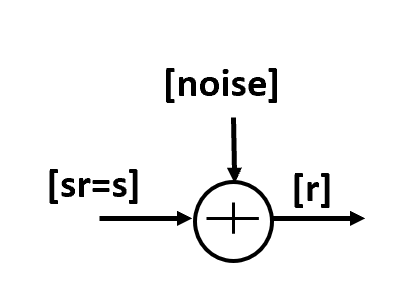

The signal is characterized by its energy Eb in a bit interval Ts or, equivalently, by its power P=Eb/Ts. The noise is characterized by its (on-sided) power spectral density N0 or equivalently, by its power  Pnoise=N0*fs/2 in the band [0, fs/2].At the output of the channel, the signal is characterized by the Signal-to-Noise Ratio.

% ********* Noise generation and sum with the received signal
figure
sr=s;
P=(1/length(sr))*sum(sr.^2); % Estimation of the mean power of the signal
EbN0=10^(0.1*EbN0_dB); % SNR expressed in linear units
sigman=sqrt(P*fs/(2*Br*EbN0)); % calculation of the noise's standard deviation
noise=sigman.*randn(1,length(sr)); % generation of the Gaussian noise
r=sr+noise; % addition of the noise to the received signal

**Demodulator specifications**

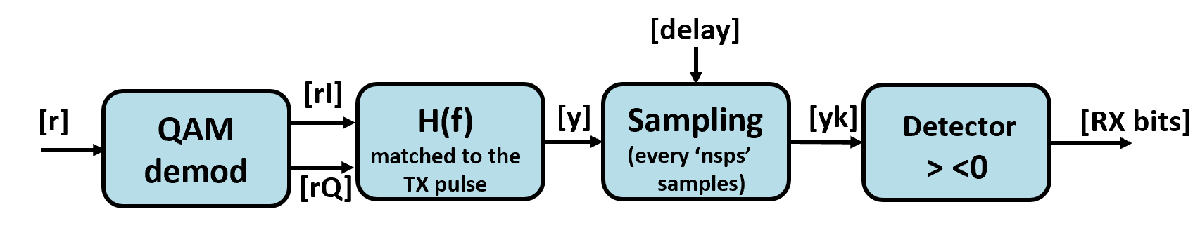

**QAM demodulator**

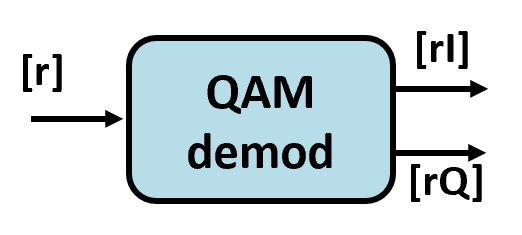

% ********* QAM demodulator
[rI,rQ,DelayQAM]=DeModQAM_2023(r,fc,T,fs,psi); % demodulate the signal
% ********* Matched filter
r=rI+1i*rQ;

**filtering with the matched filter**

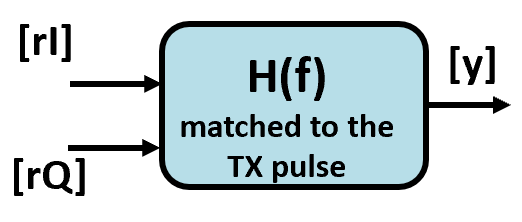

y=conv(r,h)/nsps; % filtering with the matched filter

**Sampler**

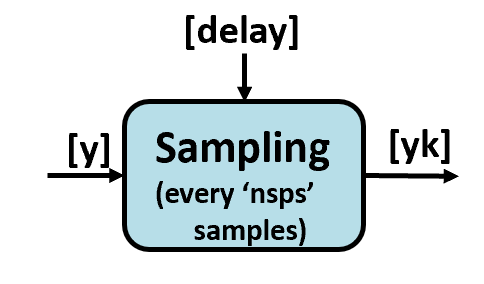

% ********* Sampler
% compute the overall delay introduced by the TX and RX filters
delay=round (2*DelayPAM+DelayQAM);
% sample the signal every symbol time accounting for the delay
yk = y(delay:nsps:nsps*nbits+delay-1);

**Detector**

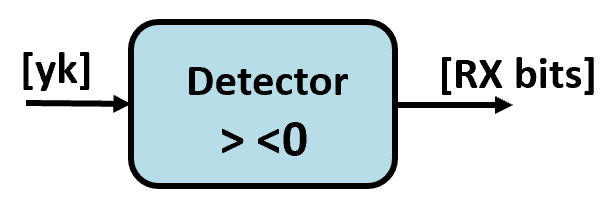

% ********* Detector
RXdata=real(yk) > 0; % take only the real part

**Bit Error Rate (BER) estimate**

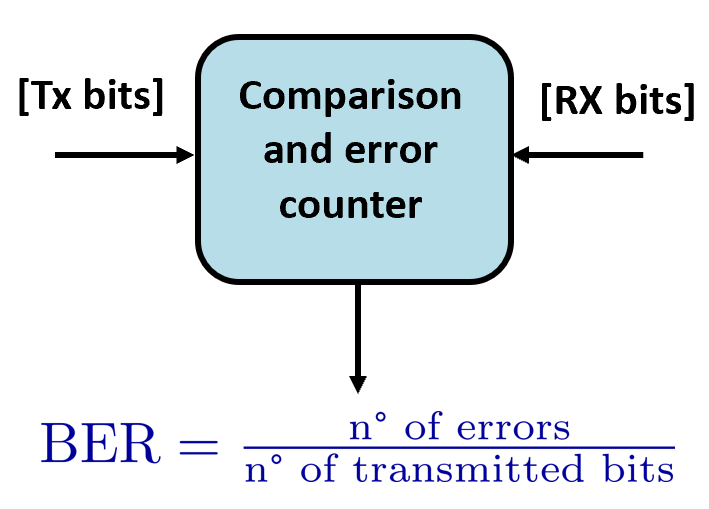

% ********* Bit Error Rate (BER) estimate
noe=sum(abs(source_bits-RXdata)); % Errors count
nod=length(source_bits);
SNRdB(index)=EbN0_dB;
ber(index)=noe/nod; % Estimate the BER
fprintf('EbNo=%.1f (dB) BER=%g\n',SNRdB(index),ber(index));
index=index+1;
% ********* End of Monte Carlo simulation
end

EbNo=1.0 (dB) BER=0.06102
EbNo=2.0 (dB) BER=0.03993
EbNo=3.0 (dB) BER=0.02474
EbNo=4.0 (dB) BER=0.0144
EbNo=5.0 (dB) BER=0.00732
EbNo=6.0 (dB) BER=0.00301
EbNo=7.0 (dB) BER=0.00094
EbNo=8.0 (dB) BER=0.00024
EbNo=9.0 (dB) BER=6e-05
EbNo=10.0 (dB) BER=0


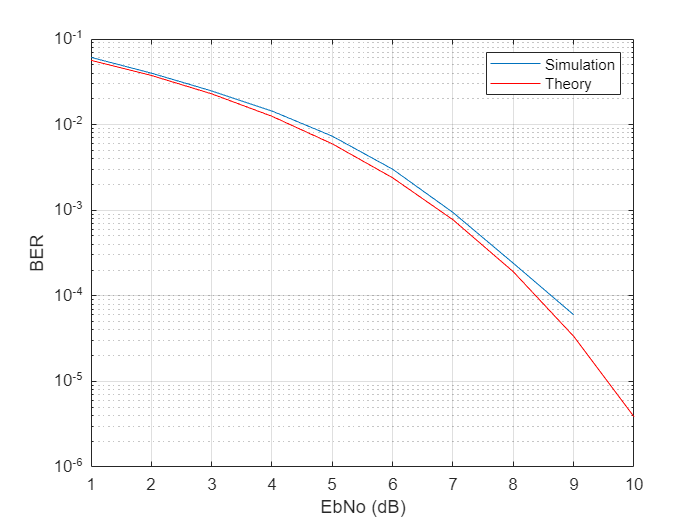

% ********* BER vs EbN0 plot
figure
semilogy(SNRdB,ber);
xlabel('EbNo (dB)');
ylabel('BER');
grid on
hold on
SNR=10.^(0.1*SNRdB);
Pb=0.5*erfc(sqrt(SNR));
plot(SNRdB,Pb,'r')
legend('Simulation', 'Theory')

This picture above gives the information of the relationship between EbN0 and BER, It can be concluded that with the incraesing value of EbN0, the number BER gets lower and lower.Which means a signals with higher EbN0 represent a higher quality of signals. The theoretical results are slightly lower than the simulation results, but this lower part of the value can be ignored. Because of the limitation of computing power this activity can not run a large number of bits, the BER is 0 when  EbN0=9 or 10.

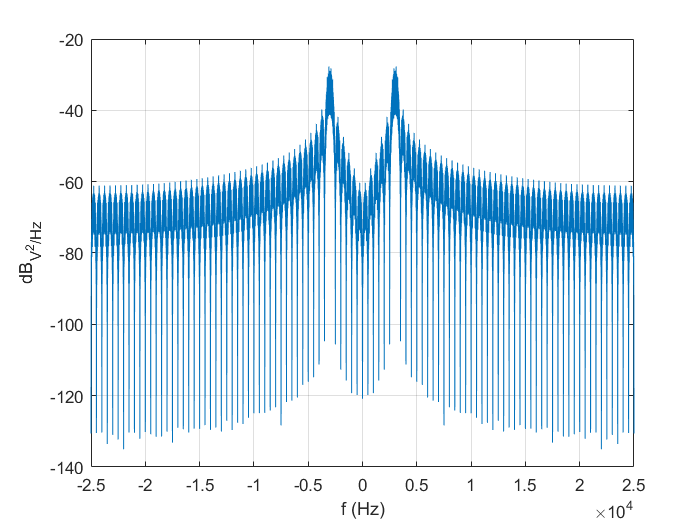

% ********* Spectrum plot
figure
PlotSpectrum_2023(s,fs);

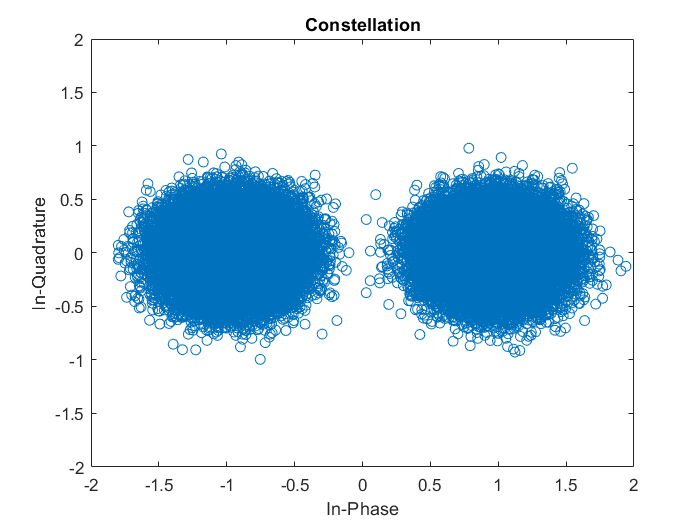

% ********* Constellation
x=real(yk);
y=imag(yk);
figure
plot(x,y,'o'), axis ([-2 2 -2 2]);
title('Constellation');
xlabel('In-Phase');
ylabel('In-Quadrature');

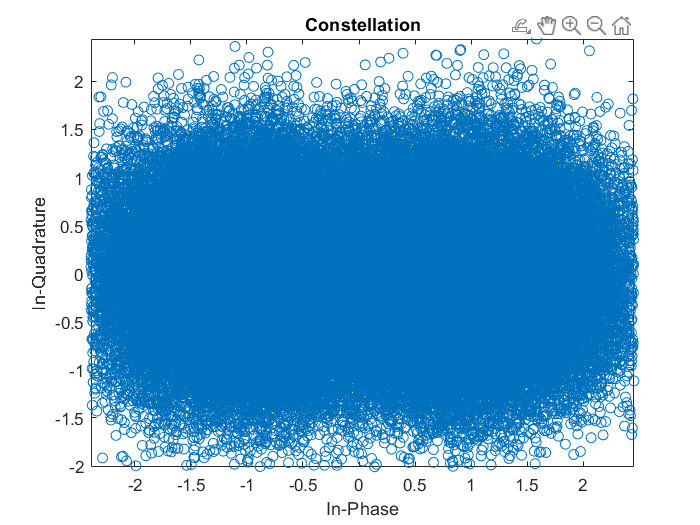

This picture is plotteed with parameter nbits=100000*bits_per_symbol,SNR=1

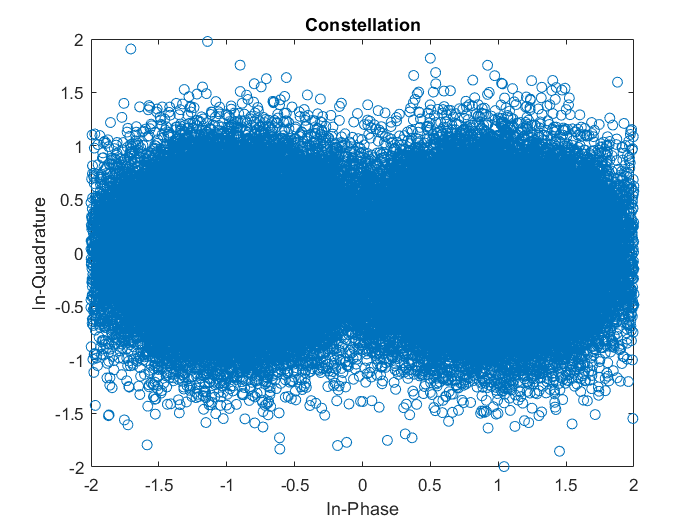

This picture is plotteed with parameter nbits=100000*bits_per_symbol,SNR=4

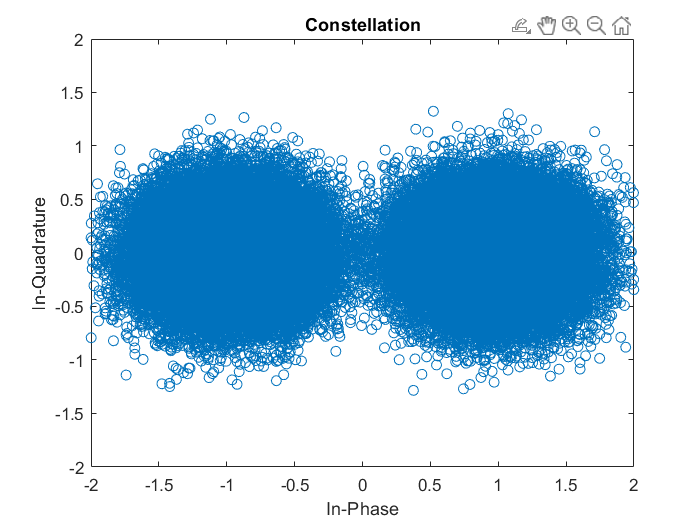

This picture is plotteed with parameter nbits=100000*bits_per_symbol,SNR=7

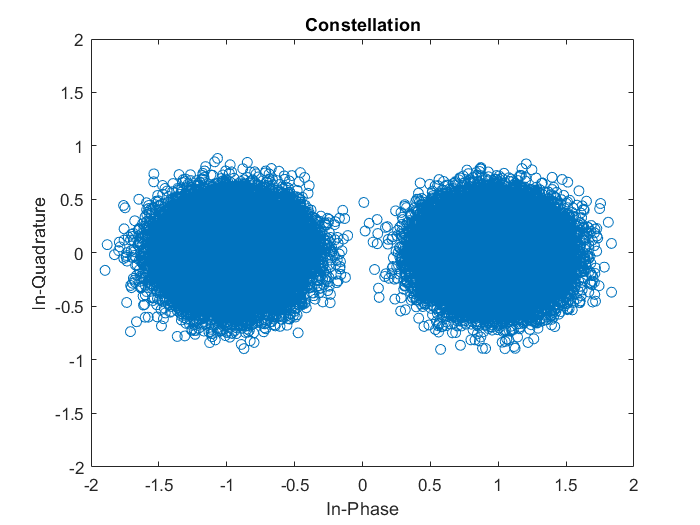

This picture is plotteed with parameter nbits=100000*bits_per_symbol,SNR=10

These pictures above are constellation for different values of the SNR.The higher value of SNR, the larger average distance between 1 and -1, so It is much easier to detect the correct information. This is correspond with the result of BbN0-BER.

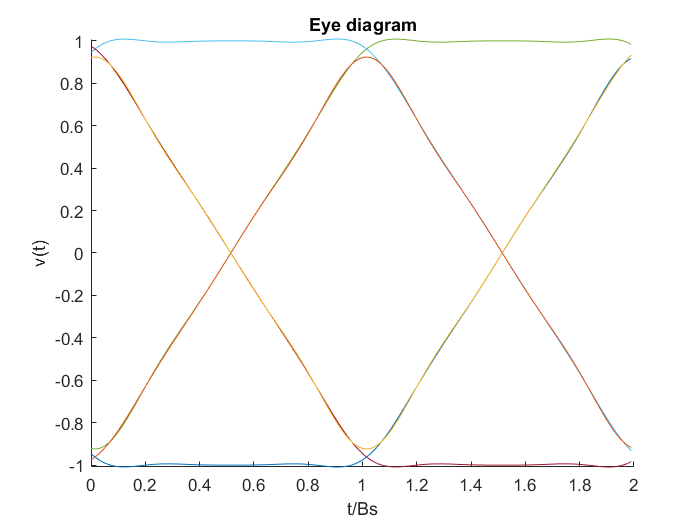

% ********* Eye diagram
H=2; % number of observation symbols
[yi,yq,DelayQAM]=DeModQAM_2023(sr,fc,T,fs,psi); % demodulate the signal
vt0=conv(yi,h)/nsps;
mm=max(abs(vt0));
x1=0:H*nsps-1;
x2=x1./nsps;
figure;
hold on
for iii=1:10
x=x1+iii*nsps+delay-1;
y=real(vt0(x)); % plot the in-phase via
plot (x2,y), axis([0 H -mm mm]);
end
title('Eye diagram');
xlabel('t/Bs');
ylabel('v(t)');

This is the eye diagram with no noise. It can easily detect the signal of 1 and -1.